# 测试(拦截)

clc
clear
close all
addpath("src\");

## C-W拦截

MU = 398600.4118; % km
r  = 42164.169; % km
n  = sqrt(MU / r /r / r); % rad/s
tf = 6000; % s
x0 = [0 -30 0 0 0 0]'; % km, km/s
acc = 2e-6;
tspan = 1; % s

辅助参数

ap.n = n;
ap.acc = acc;
ap.tspan = tspan;
ap.MU = MU;

### 间接法

#### 遗传


Single objective optimization:
4 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              200            24.3            1006        0
    2              295           22.45           670.3        0
    3              390           11.46           426.9        0
    4              485           2.961           298.3        0
    5              580            2.54           216.9        0
    6              675           1.401           102.5        0
    7              770           1.374           94.63        0
    8              865           1.002            76.9        0
    9              960          0.9729           36.25        0
   10             1055          0.6713           3.674        0
   11      

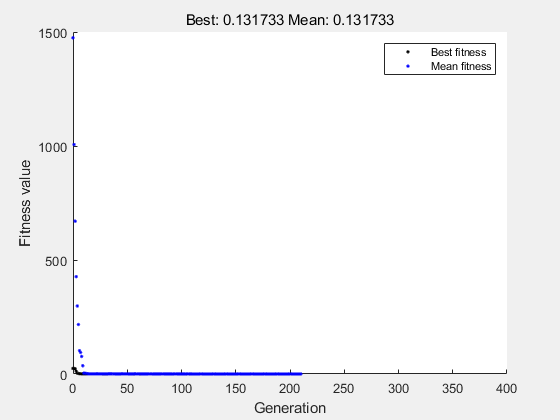

tic
[s, lambda, tf] = CwInterTimeGa(x0, tf, ap);

toc

历时 200.063527 秒。


lambda(1 : 3)

ans =     4.5343
  -93.4227
   -0.0000


lambda(4 : 6)

ans = 1.0e+05 *

    1.9576
   -4.6011
   -0.0000


tf

tf = 5.4773e+03

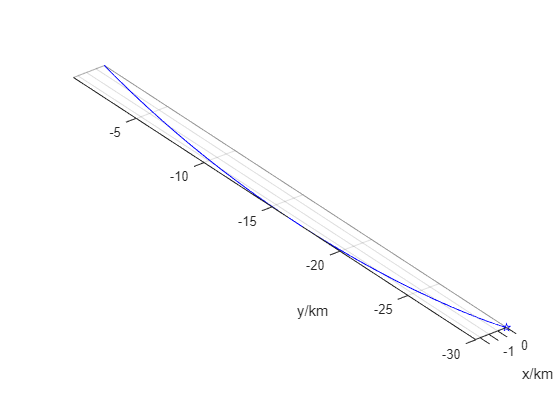

figure
plot3(s(:, 2), s(:, 3), s(:, 4), 'b')
hold on
plot3(s(1, 2), s(1, 3), s(1, 4), 'bp')
grid on
axis equal
xlabel('x/km')
ylabel('y/km')
zlabel('z/km')

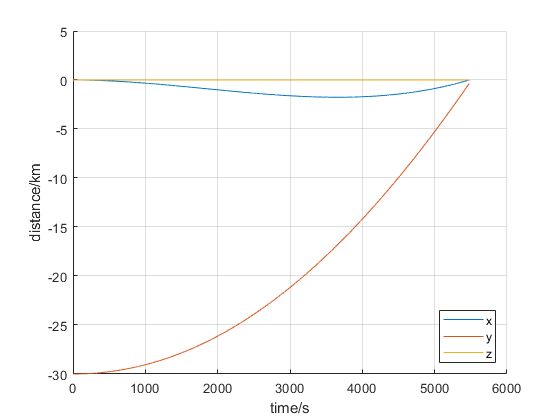

figure
hold on
plot(s(:, 1), -s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/km')

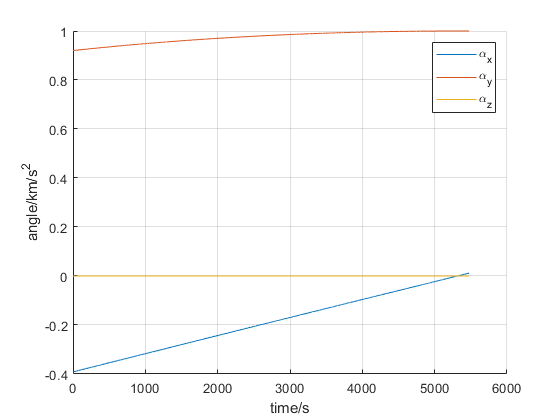

figure
hold on
plot(s(:, 1), s(:, 14 : 16))
grid on
legend('\alpha_x', '\alpha_y', '\alpha_z')
xlabel('time/s')
ylabel('angle/km/s^2')

#### fmincon

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    5.477321e+03    1.001e+00    9.307e-10
    1      10    5.478921e+03    1.001e+00    5.052e-08    1.600e+00
    2      18    5.478348e+03    1.001e+00    2.776e-07    5.734e-01
    3      23    5.481559e+03    1.001e+00    1.940e-07    3.211e+00
    4      28    5.486055e+03    1.001e+00    1.149e-09    4.496e+00
    5      33    5.511230e+03    1.001e+00    6.323e-10    2.518e+01
    6      48    5.511807e+03    1.001e+00    1.087e-10    5.775e-01
    7      55    5.509785e+03    1.001e+00    1.166e+05    2.021e+00
    8      66    5.509268e+03    1.001e+00    7.181e-09    5.174e-01
    9      72    5.510427e+03    1.001e+00    1.504e-05    1.159e+00
   10      83    5.509389e+03    1.001e+00    3.563e-10    1.038e+00
   11      94    5.509123e+03    1.001e+00    9.884e-10    2.659e-01
   12     106    5.509028e+03    1.001e+00    1

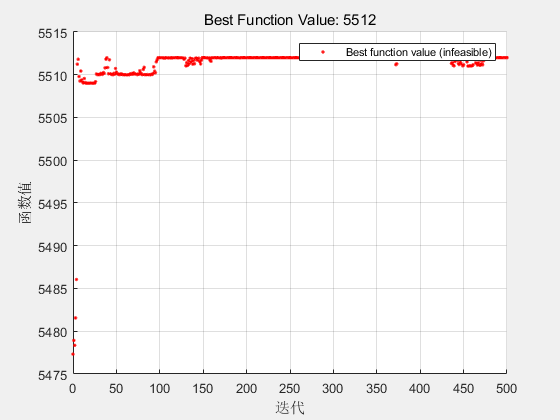


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 5.000000e+02.



xf = zeros(6, 1);
tic
[s,fval,exitflag,output] = IndirOptTime6(@(t, x) CwTimeOpt(t, x, ap), x0, xf, tf, ap, [lambda; tf]);

toc

历时 69.499520 秒。


lambda(1 : 3)

ans =     4.5343
  -93.4227
   -0.0000


lambda(4 : 6)

ans = 1.0e+05 *

    1.9576
   -4.6011
   -0.0000


tf = s(end, 1)

tf = 5511

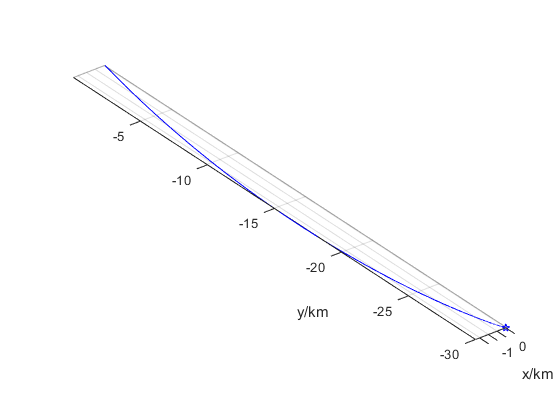

[t, s] = ode45(@(t, x) CwTimeOpt(t, x, ap), 0 : ap.tspan : tf, [x0; lambda]);
[~, B] = Cw(ap.n);
u = zeros(length(t), 3);
for i = 1 : length(t)
    u(i, 1 : 3) = -(B' * s(i, 7 : 12)' / norm(B' * s(i, 7 : 12)'))';
end
s = [t, s, u];
figure
plot3(s(:, 2), s(:, 3), s(:, 4), 'b')
hold on
plot3(s(1, 2), s(1, 3), s(1, 4), 'bp')
grid on
axis equal
xlabel('x/km')
ylabel('y/km')
zlabel('z/km')

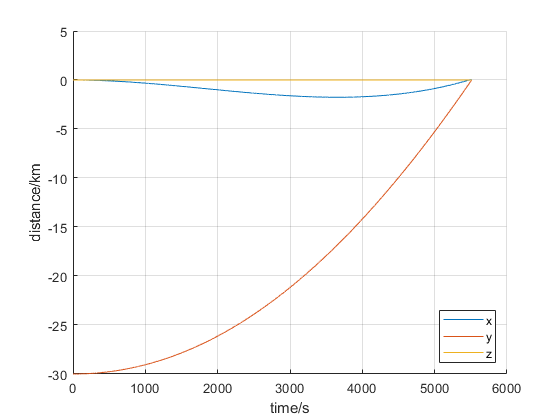

figure
hold on
plot(s(:, 1), -s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/km')

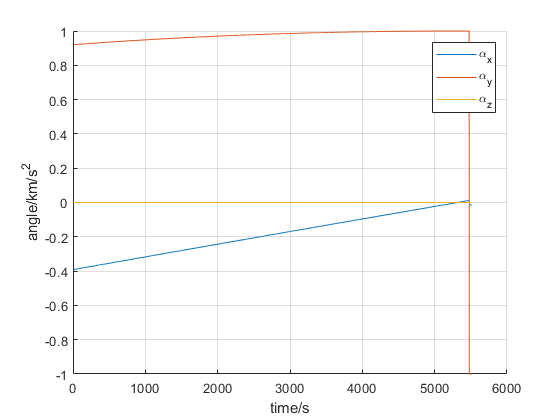

figure
hold on
plot(s(:, 1), s(:, 14 : 16))
grid on
legend('\alpha_x', '\alpha_y', '\alpha_z')
xlabel('time/s')
ylabel('angle/km/s^2')

## 二体拦截

MU = 398600.4118; % km
RE = 6371.137;
g = MU / RE^2; % km / s^2
coe_p = [6578.165, 0, 30, 10, 0, 0];
coe_e = [6578.165, 0, 50, 30, 0, 10];
coe_p(3 : 6) = coe_p(3 : 6) * pi / 180;
coe_e(3 : 6) = coe_e(3 : 6) * pi / 180;
[rp, vp] = Coe2Eci(coe_p, MU);
[re, ve] = Coe2Eci(coe_e, MU);
xp = [rp; vp];
xe = [re; ve];
acc = 0.1 * g;
tf = 3000; % s
tspan = 1; % s

辅助参数

ap.acc = acc;
ap.tspan = tspan;
ap.MU = MU;

### 不加控制

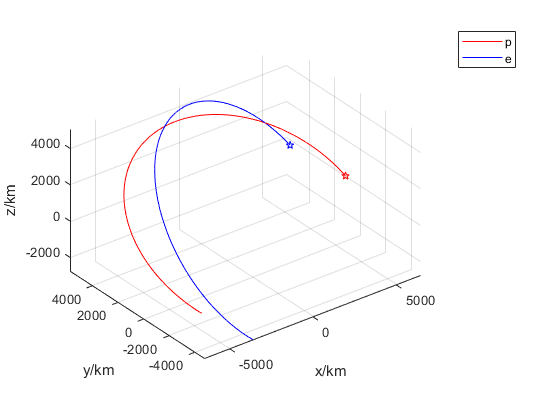

[t, sp] = ode45(@(t, x) TwoBodyEq(t, x, zeros(3, 1), ap), 0 : tspan : tf, xp);
sp = [t, sp];
[t, se] = ode45(@(t, x) TwoBodyEq(t, x, zeros(3, 1), ap), 0 : tspan : tf, xe);
se = [t, se];
figure
plot3(sp(:, 2), sp(:, 3), sp(:, 4), 'r')
hold on
plot3(se(:, 2), se(:, 3), se(:, 4), 'b')
plot3(xp(1), xp(2), xp(3), 'rp')
plot3(xe(1), xe(2), xe(3), 'bp')
grid on
axis equal
xlabel('x/km')
ylabel('y/km')
zlabel('z/km')
legend('p', 'e')

### 间接法

#### 遗传


Single objective optimization:
7 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              400        2.34e+04       2.708e+05        0
    2              590       1.618e+04       2.148e+05        0
    3              780       1.423e+04       1.574e+05        0
    4              970       1.297e+04       1.058e+05        0
    5             1160       1.293e+04       6.788e+04        0
    6             1350       1.293e+04       4.475e+04        1
    7             1540            9880       3.212e+04        0
    8             1730            9866       2.878e+04        0
    9             1920            9632       2.589e+04        0
   10             2110            9628       2.198e+04        0
   11      

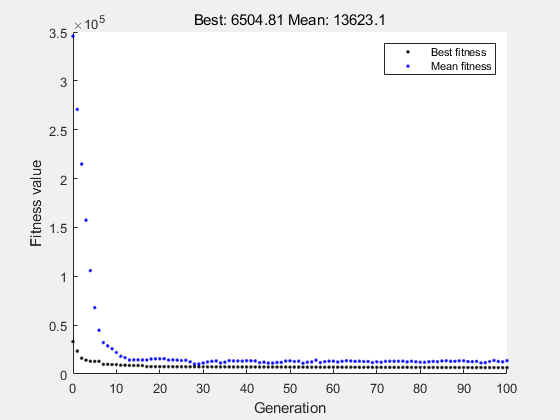

tic
[sp, se, lambda, tf] = TwoBodyInterGa(xp, xe, tf, ap);

toc

历时 250.288648 秒。


lambda(1 : 3)

ans =    -0.3563
   -1.9902
    1.1622


lambda(4 : 6)

ans =    26.4578
    1.4282
   28.2744


tf

tf = 2.6182e+03

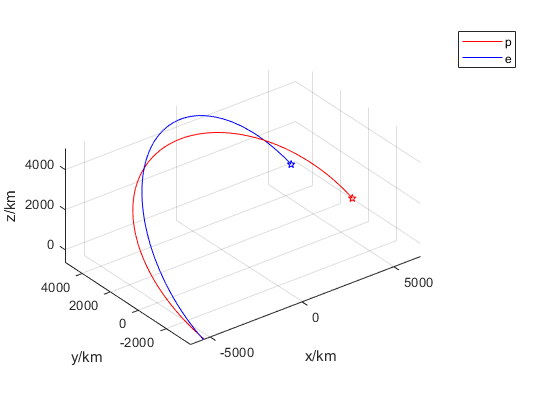

figure
plot3(sp(:, 2), sp(:, 3), sp(:, 4), 'r')
hold on
plot3(se(:, 2), se(:, 3), se(:, 4), 'b')
plot3(xp(1), xp(2), xp(3), 'rp')
plot3(xe(1), xe(2), xe(3), 'bp')
grid on
axis equal
xlabel('x/km')
ylabel('y/km')
zlabel('z/km')
legend('p', 'e')

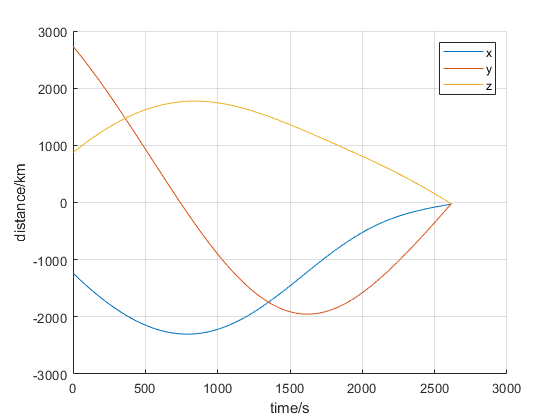

figure
hold on
plot(sp(:, 1), se(:, 2 : 4) - sp(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/km')

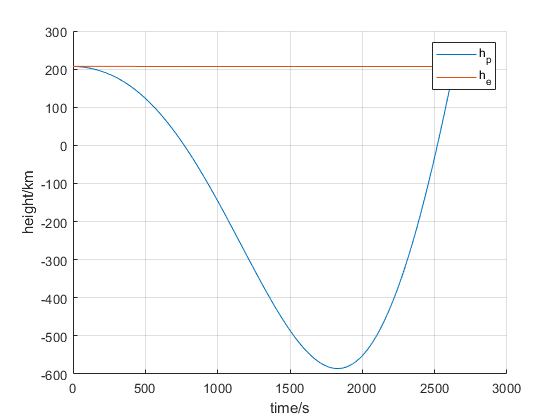

hp = sp(:, 1);
he = sp(:, 1);
for i = 1 : length(hp)
    hp(i) = norm(sp(i, 2 : 4)) - RE;
    he(i) = norm(se(i, 2 : 4)) - RE;
end
figure
hold on
plot(sp(:, 1), hp)
plot(se(:, 1), he)
grid on
legend('h_p', 'h_e')
xlabel('time/s')
ylabel('height/km')

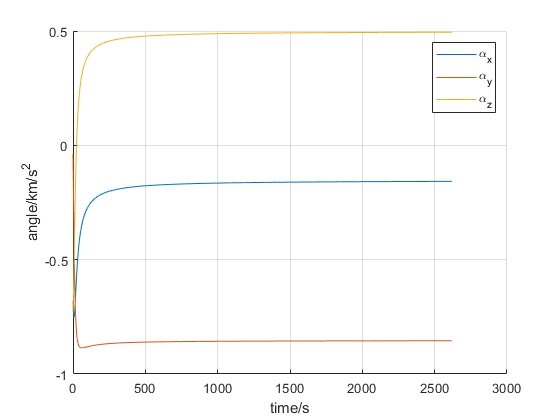

figure
hold on
plot(sp(:, 1), sp(:, 14 : 16))
grid on
legend('\alpha_x', '\alpha_y', '\alpha_z')
xlabel('time/s')
ylabel('angle/km/s^2')

#### fmincon

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    2.618217e+03    5.213e+03    1.000e+00
    1      16    2.617455e+03    1.239e+03    1.000e+00    1.219e+02
    2      24    2.617519e+03    1.199e+03    1.000e+00    7.240e-01
    3      32    2.619919e+03    8.512e+02    1.000e+00    2.410e+00


    4      40    2.615312e+03    7.688e+02    1.000e+00    4.608e+00
    5      49    2.615307e+03    7.679e+02    2.399e+01    3.954e-01
    6      58    2.613518e+03    5.230e+02    1.404e+04    1.146e+02
    7      67    2.612911e+03    2.614e+02    6.574e+04    6.722e+00
    8      76    2.612069e+03    1.307e+02    1.696e+05    1.599e+00
    9      85    2.606035e+03    6.521e+01    3.787e+05    6.097e+00
   10      96    2.616212e+03    5.727e+01    4.555e+05    1.018e+01
   11     107    2.606852e+03    4.993e+01    5.128e+05    9.363e+00
   12     117    2.621725e+03    3.767e+01    7.544e+05    1.487e+01
   13     128    2.609588e+03    3.281e+01    8.367e+05    1.214e+01
   14     137    2.615567e+03    3.214e+01    1.967e+06    5.980e+00
   15     147    2.607107e+03    3.442e+01    2.666e+06    8.462e+00
   16     167    2.607147e+03    3.490e+01    1.000e+00    6.610e-02
   17     176    2.607213e+03    3.487e+01    1.000e+00    6.611e-02
   18     187    2.618476e+03    2

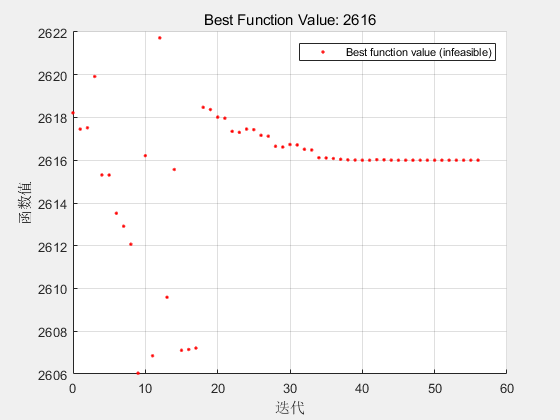


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



tic
[sp, se, lambda, tf] = TwoBodyInter(xp, xe, tf, ap, [lambda; tf]);

toc

历时 15.239558 秒。


lambda(1 : 3)

ans =     0.0003
   -0.0026
    0.0004


lambda(4 : 6)

ans =     0.1105
   -0.3282
    0.1290


tf

tf = 2.6160e+03

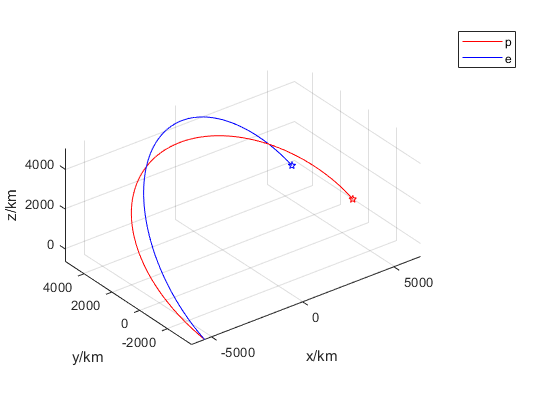

figure
plot3(sp(:, 2), sp(:, 3), sp(:, 4), 'r')
hold on
plot3(se(:, 2), se(:, 3), se(:, 4), 'b')
plot3(xp(1), xp(2), xp(3), 'rp')
plot3(xe(1), xe(2), xe(3), 'bp')
grid on
axis equal
xlabel('x/km')
ylabel('y/km')
zlabel('z/km')
legend('p', 'e')

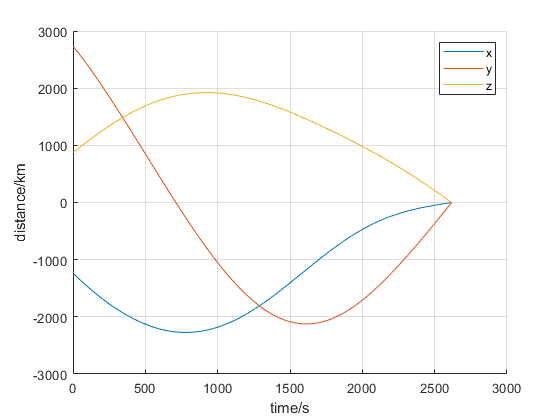

figure
hold on
plot(sp(:, 1), se(:, 2 : 4) - sp(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/km')

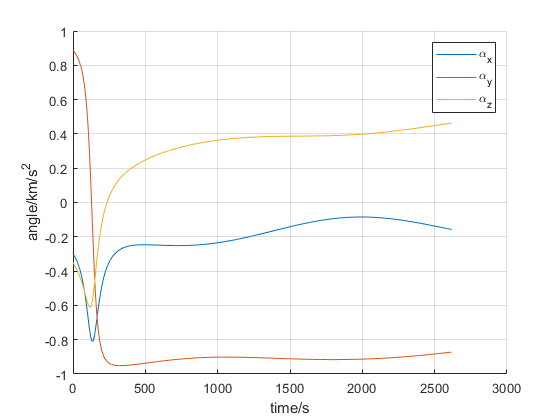

figure
hold on
plot(sp(:, 1), sp(:, 14 : 16))
grid on
legend('\alpha_x', '\alpha_y', '\alpha_z')
xlabel('time/s')
ylabel('angle/km/s^2')